This File discusses feature extration techniques for ripples and 

evaluates them using a manually labeled dataset

In the first step we import the necessary libraries and the downsampled recording (lfp)

Adjust the paths to reflect the location of your local copy of the Buszaki Lab Buzcode Repo

as well as your local copy of the Multi Area Bundle Project Repo 

% Import libaries
% Buzcode GitHub Repo
addpath(genpath("C:\Users\Linus Meienberg\Documents\Buzcode"));
% multi area bundle project repo / Ripple Analysis Folder
addpath(genpath('C:\Users\Linus Meienberg\Documents\MultiAreaBundleProject\RippleAnalysis'))

%% Script Parameters
% path to lfp file
lfp.filename = 'D:\INI\SemesterArbeitBaran\rTBY33\7_freely_behav_220315_145519\amplifier_ds.dat';
lfp.samplerate = 2000;
lfp.num_channels = 256;
lfp.ripple_channels = [121,120,85,84,86,83,87,82,88,119]; % channel number of contigous sites that show ripples
lfp.main_channel = 1; % index of the main channel for ripple detection in lfp.ripple_channels

%% Import LFP data
lfp.data = detrend(double(ImporterDAT_multi(lfp.filename,lfp.num_channels,lfp.ripple_channels))'); % detrend and subsequent op require (time,channels) format

Error using waitbar (line 101)
The second argument must be a message character vector or a handle to an existing waitbar.

Error in ImporterDAT_multi (line 67)
    waitbar(perc/100,h,sprintf('%.1f%% along...',perc))

lfp.timestamps = (1:size(lfp.data,1))/lfp.samplerate;

%% Filter Data
bandpass = designfilt('bandpassfir','FilterOrder',600,'StopbandFrequency1',125,'PassbandFrequency1',130,'PassbandFrequency2',200,'StopbandFrequency2',205,'SampleRate',2000);
lowpass = designfilt('lowpassfir','FilterOrder',600,'PassbandFrequency',245,'StopbandFrequency',250,'SampleRate',2000);
lfp.bandpass = filtfilt(bandpass,lfp.data);
lfp.lowpass = filtfilt(lowpass,lfp.data);

%% Bandpass power
lfp.bandpass_power = abs(hilbert(lfp.bandpass));


In the next step we import a manually labeled set of ripple events and calculate basic features for each ripple

Change the path to reflect the location of the Multi Area Bundle Repo on your machine.

%% load ripple events
load("C:\Users\Linus Meienberg\Documents\MultiAreaBundleProject\RippleAnalysis\RippleDetection\rTBY33S7_DS0505_manual.mat")
ripples.eventID = ripple_classes;
ripples.timestamps = ripple_timestamps;
ripples.n = size(ripples.timestamps,1);
ripples.peaks = zeros(ripples.n,1);
ripples.amplitude = zeros(ripples.n,1);
ripples.amplitudeUnits = "";

% declare additional features calculated for every ripple
ripples.duration = ripples.timestamps(:,2) - ripples.timestamps(:,1);
ripples.lowpass_mean = zeros(ripples.n,1);
ripples.lowpass_std = zeros(ripples.n,1);
ripples.lowpass_meanChannelSpread = zeros(ripples.n,1);
ripples.lowpass_min = zeros(ripples.n,1);
ripples.lowpass_max = zeros(ripples.n,1);
ripples.bandpass_mean = zeros(ripples.n,1);
ripples.bandpass_std = zeros(ripples.n,1);
ripples.bandpass_peak2peak = zeros(ripples.n,1);
ripples.bandpass_meanFreq = zeros(ripples.n,1);
ripples.bandpass_meanAbsSlope = zeros(ripples.n,1);
ripples.bandpass_maxSlope = zeros(ripples.n,1);

%% Calculate Putative Peak Timepoints and some features for clustering

for i = 1:ripples.n
    % get ripple event
    ripple_interval = ripples.timestamps(i,:);
    ripple_frames = lfp.timestamps >= ripple_interval(1) & lfp.timestamps <= ripple_interval(2);
    bandpassPower_slice = lfp.bandpass_power(ripple_frames,:);
    bandpassPower_mean = mean(bandpassPower_slice,2); % average power over channels
    [maxValue, maxIndex] = max(bandpassPower_mean);
    ripples.peaks(i) = (find(ripple_frames,1) + maxIndex) / lfp.samplerate;
    ripples.amplitude(i) = maxValue;

    % generate some features for clustering
    lowpass_slice = lfp.lowpass(ripple_frames,lfp.main_channel);
    bandpass_slice = lfp.bandpass(ripple_frames,lfp.main_channel);
    
    % extract min, max, mean and sd of lowpass and bandpass
    ripples.lowpass_min(i) = min(lowpass_slice);
    ripples.lowpass_max(i) = max(lowpass_slice);
    ripples.lowpass_mean(i) = mean(lowpass_slice);
    ripples.lowpass_std(i) = std(lowpass_slice);
    ripples.lowpass_meanChannelSpread(i) = mean(abs(lfp.lowpass(ripple_frames,:) - mean(lfp.lowpass(ripple_frames,:),2)),[1 2]);
    ripples.bandpass_mean(i) = mean(bandpass_slice);
    ripples.bandpass_std(i) = std(bandpass_slice);
    % calculate max peak2peak distance 
    ripples.bandpass_peak2peak(i) = peak2peak(bandpass_slice);
    % calculate mean frequency of the bandpass filtered signal
    ripples.bandpass_meanFreq(i) = mean(instfreq(bandpass_slice,lfp.samplerate));
    % calculate derivative and find peak / mean signal slope
    ripples.bandpass_maxSlope(i) = max(diff(bandpass_slice));
    ripples.bandpass_meanAbsSlope(i) = mean(abs(diff(bandpass_slice)));
end

%% Assemble feature Table
ripples.features = [ ripples.lowpass_min ripples.lowpass_max ripples.lowpass_mean ripples.lowpass_std ...
    ripples.lowpass_meanChannelSpread ripples.bandpass_mean ripples.bandpass_std ...
    ripples.bandpass_maxSlope ripples.bandpass_meanAbsSlope ripples.bandpass_meanFreq ...
    ripples.bandpass_peak2peak];
varnames = {'lowpass min','lowpass max','lowpass mean','lowpass std','lowpass mean Channel spread','bandpass mean','bandpass std','bandpass maxSlope',...
    'bandpass meanAbsSlope','bandpass meanFreq','bandpass p2p'};

As a first step we can visualize the distribution of the different ripple classes in the feature space

The plot below shows the class wise distribution of each feature in the diagonal. The scatterplots off-diagonal show the distribution of classes in the plane defined by every combination of two features

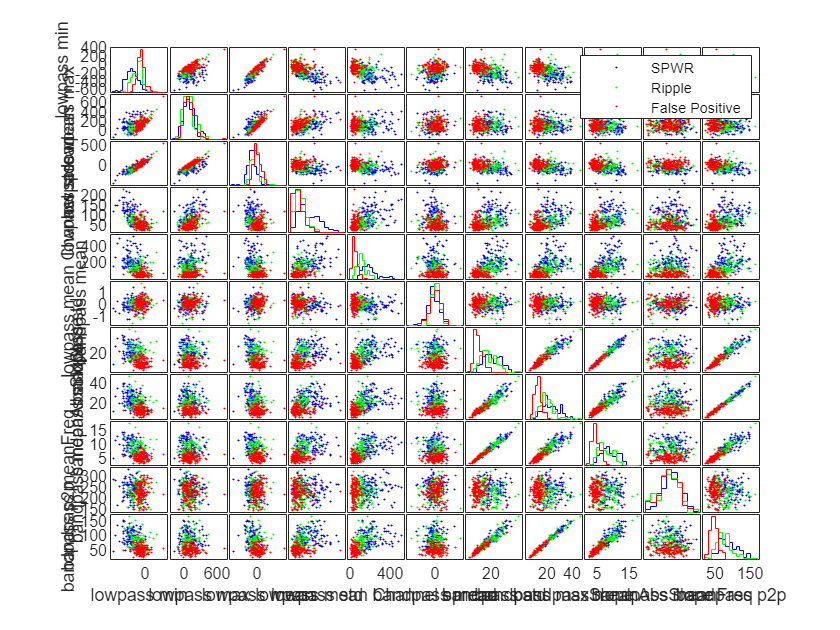

figure()
group = categorical(ripples.eventID,[0 1 2],{'SPWR','Ripple','False Positive'});
gplotmatrix(ripples.features,[],group,[],[],[],[],[],varnames)
legend('sharp wave ripple','ripple','false positive')

Visualize some Ripple Events to get a feeling for the data.

Note that we have imported multi channel data from the lfp file !

In the lowpass and bandpass data each channel is visible as a colored line

The bandpass power (hilbert transform) plots each channel in its own row.

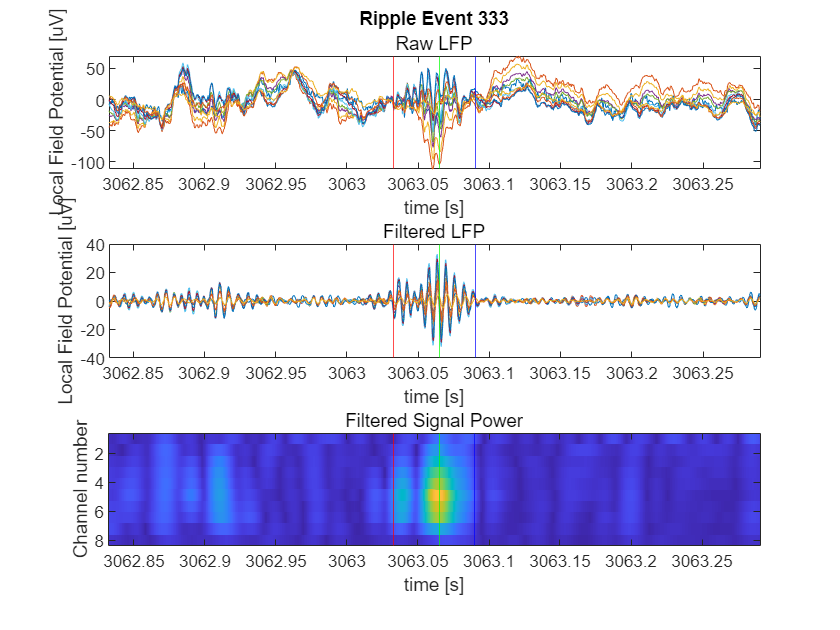

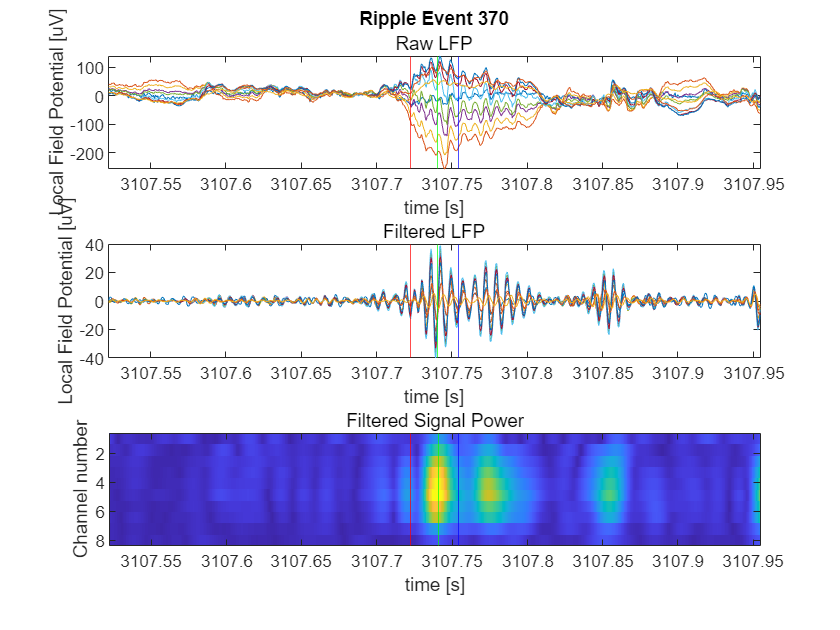

%% Visualize some Ripple Events
padding = 0.2; % [s] how much of preceding and following signal to show
voltageScaling = 0.195; % [uV / bit]
eventSubset = randsample(size(ripples.timestamps,1),2)';

for i = eventSubset
    % retrieve the interval in which ripple i was detected
    ripple_interval = ripples.timestamps(i,:);
    ripple_vicinity = ripple_interval + [-padding,padding];
    % create a boolean index vecor for the corresponding frames of the
    % recording, extract the timestamps, raw voltage trace and filtered
    % voltage trace
    ripple_frames = (lfp.timestamps >= ripple_vicinity(1) & ripple_vicinity(2) >= lfp.timestamps);
    ripple_data_timestamps = lfp.timestamps(ripple_frames);
    ripple_data_raw = lfp.data(ripple_frames,:) * voltageScaling;
    ripple_data_bp = lfp.bandpass(ripple_frames,:) * voltageScaling;
    ripple_data_power = lfp.bandpass_power(ripple_frames,:);
    % Plot raw LFP event
    figure(i)
    subplot(3,1,1)
    plot(ripple_data_timestamps,ripple_data_raw);
    title("Ripple Event " + i);
    subtitle("Raw LFP");
    xlabel('time [s]');
    ylabel('Local Field Potential [uV]');
    axis tight
    hold on;
    xline(ripple_interval(1),'r');
    xline(ripple_interval(2),'b');
    xline(ripples.peaks(i),'g');
    hold off;
    % Plot filtered LFP event
    subplot(3,1,2)
    plot(ripple_data_timestamps,ripple_data_bp);
    subtitle("Filtered LFP");
    xlabel('time [s]');
    ylabel('Local Field Potential [uV]');
    axis tight
    ylim([-40 40]);
    hold on;
    xline(ripple_interval(1),'r');
    xline(ripple_interval(2),'b');
    xline(ripples.peaks(i),'g');
    hold off;
    % Plot banpass signal power
    subplot(3,1,3)
    %plot(ripple_data_timestamps,ripple_data_power);
    clims = [0 200];
    imagesc(ripple_vicinity,[1 8],ripple_data_power',clims);
    subtitle("Filtered Signal Power");
    xlabel('time [s]');
    ylabel('Channel number');
    % axis tight
    hold on;
    xline(ripple_interval(1),'r');
    xline(ripple_interval(2),'b');
    xline(ripples.peaks(i),'g');
    hold off;
end

In the next step we extract a fixed length window around from the lfp signal around the bandpass power peak of each signal

we then refine the alignment of our ripple events

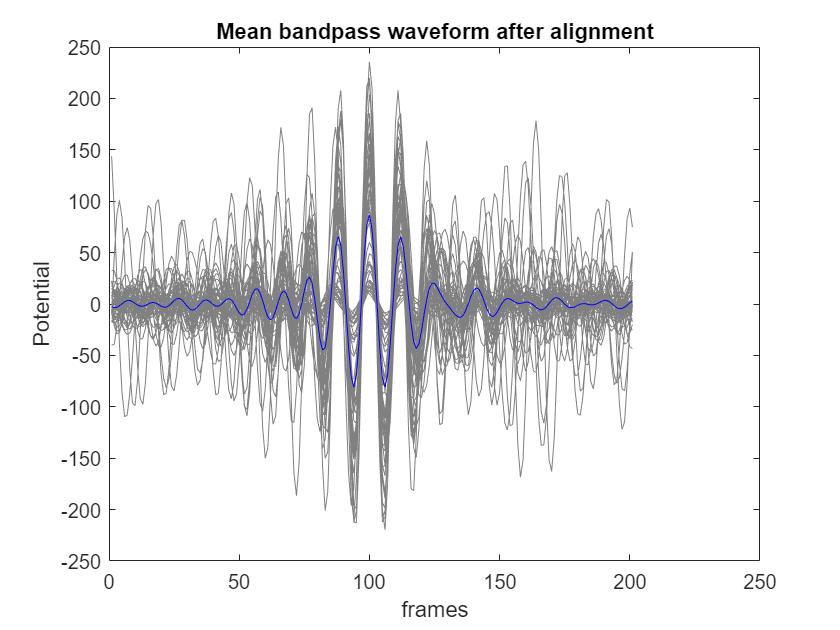

%% Set Window Length for Event Alignment
eventWindow = 0.1; % [s] duration of event window
eventWindowFrames = eventWindow*lfp.samplerate; % convert to frame number
eventWindowHalfFrames = round(eventWindowFrames /2); % extend central frame by this amount into both directions
eventWindowFrames = 2*eventWindowHalfFrames + 1; % effective episode length
%% extract ripple episodes and iteratively align them using maximization of cross correlation
clear rippleEpisodes
% Episodes have format (events x time x channels)
rippleEpisodes.peakFrames = round(ripples.peaks * lfp.samplerate);
rippleEpisodes.centralFrames = alignRipples(mean(lfp.bandpass,2), rippleEpisodes.peakFrames, eventWindowFrames);

%% extract signals 
for i = 1:ripples.n
    startFrame = rippleEpisodes.centralFrames(i) - eventWindowHalfFrames;
    endFrame = rippleEpisodes.centralFrames(i) + eventWindowHalfFrames;
    rippleEpisodes.bandpass(i,:,:) = lfp.bandpass(startFrame:endFrame,:);
    rippleEpisodes.lowpass(i,:,:) = lfp.lowpass(startFrame:endFrame,:);
    rippleEpisodes.bandpass_power(i,:,:) = lfp.bandpass_power(startFrame:endFrame,:);
end

%% show mean waveform after alignment
% here we select a single channel from the data !
plotMeanWaveform(rippleEpisodes.bandpass(:,:,5),1:ripples.n)
title("Mean bandpass waveform after alignment")

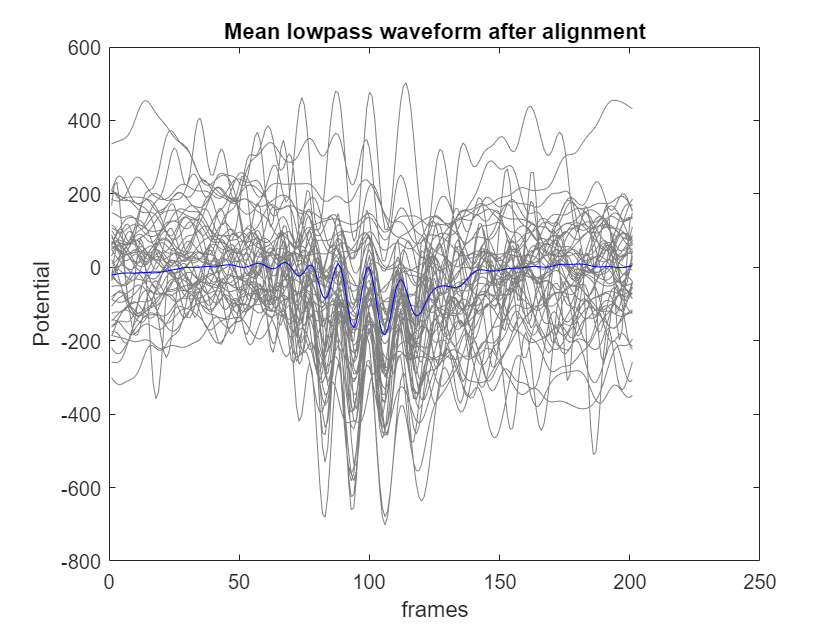

plotMeanWaveform(rippleEpisodes.lowpass(:,:,5),1:ripples.n)
title("Mean lowpass waveform after alignment")

We now begin to extract more complex feature from our ripple episodes.

First, we analyze the frequency contect of each ripple episode (the aliged fixed size window that contains the ripple event)

We can use the labels to visualize the differences in the power spectra between putative SPWRs, Ripples and false positives.

Note that the power spectra are calculated for each channel, but the plot shows the average over all instances of a class and all channels.

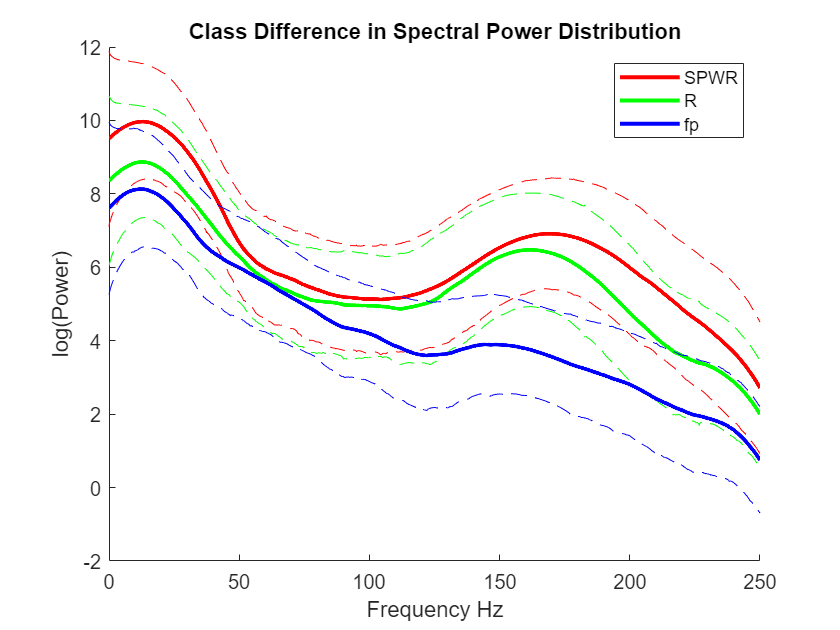

%% Compute power spectra of lowpass episodes
rippleEpisodes.spectrogram = [];
for i_event = 1:ripples.n
    ep = squeeze(rippleEpisodes.lowpass(i_event,:,:));
    ep_centered = ep - mean(ep,1); % subtract channel wise time average to decrease DC power
    [p, f] = pspectrum(ep_centered,2000,'power','FrequencyLimits',[0 250]);%,'FrequencyResolution',20);
    p = log(p);
    rippleEpisodes.spectrogram(i_event,:,:) = p;
end
rippleEpisodes.spectrogram_frequencies = f;

%% Display the power spectrum distribution based on ripple class
figure()
hold on;
group_color = ['r','g','b'];
for group = 0:2
    group_mean = mean(rippleEpisodes.spectrogram(ripples.eventID==group,:,:),[1 3]);
    group_std = std(rippleEpisodes.spectrogram(ripples.eventID==group,:,:),[],[1 3]);
    plot(rippleEpisodes.spectrogram_frequencies,group_mean-group_std,'--','Color',group_color(group+1))
    plot(rippleEpisodes.spectrogram_frequencies,group_mean,'Color',group_color(group+1),'LineWidth',2)
    plot(rippleEpisodes.spectrogram_frequencies,group_mean+group_std,"--",'Color',group_color(group+1))
end
hold off;
title('Class Difference in Spectral Power Distribution')
legend("","SPWR","","","R","","","fp","")
xlabel('Frequency Hz')
ylabel("log(Power)")

Now we can perform PCA on the channel-averaged power spectra to identify principle components of variation

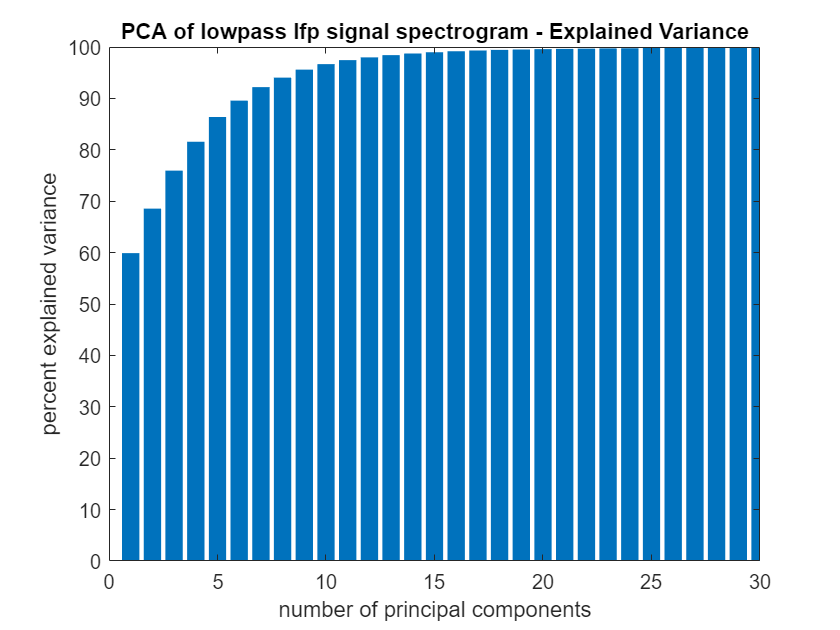

%(event x freq x channel) -> (event x freq)
data = mean(rippleEpisodes.spectrogram,3); % average over channels 
[coeff,score, ~, ~, explained, ~ ] = pca(data);
rippleEpisodes.spectrogram_features = score(:,1:5);

%% Visualize Sucess of PCA on power spectra of lowpass signal
% visualize explained variance by first n components
figure()
bar(cumsum(explained))
title('PCA of lowpass lfp signal spectrogram - Explained Variance')
xlabel('number of principal components')
ylabel('percent explained variance')
xlim([0 30])

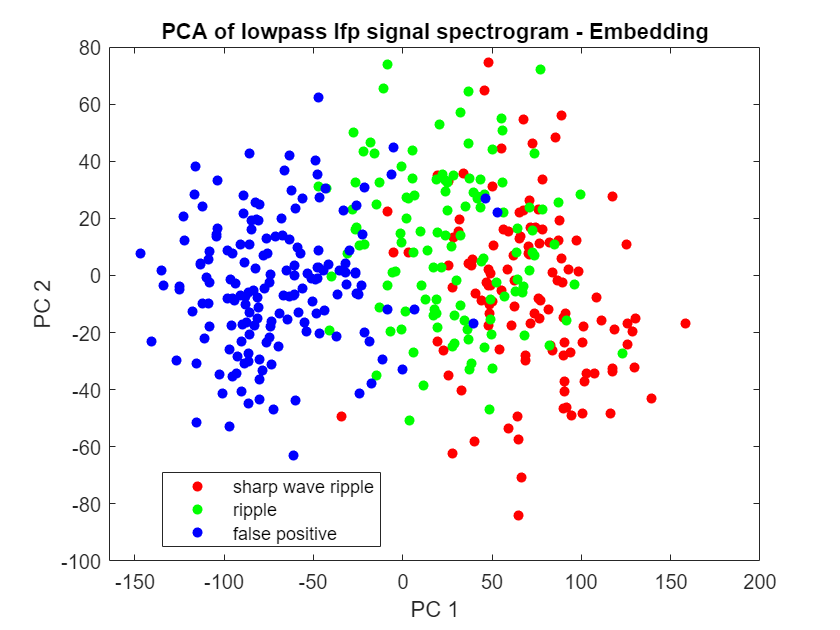


% Visualize PCA projection of ripples
figure()
gscatter(score(:,1),score(:,2), ripples.eventID)
title("PCA of lowpass lfp signal spectrogram - Embedding")
xlabel('PC 1')
ylabel('PC 2')
legend('sharp wave ripple','ripple','false positive')

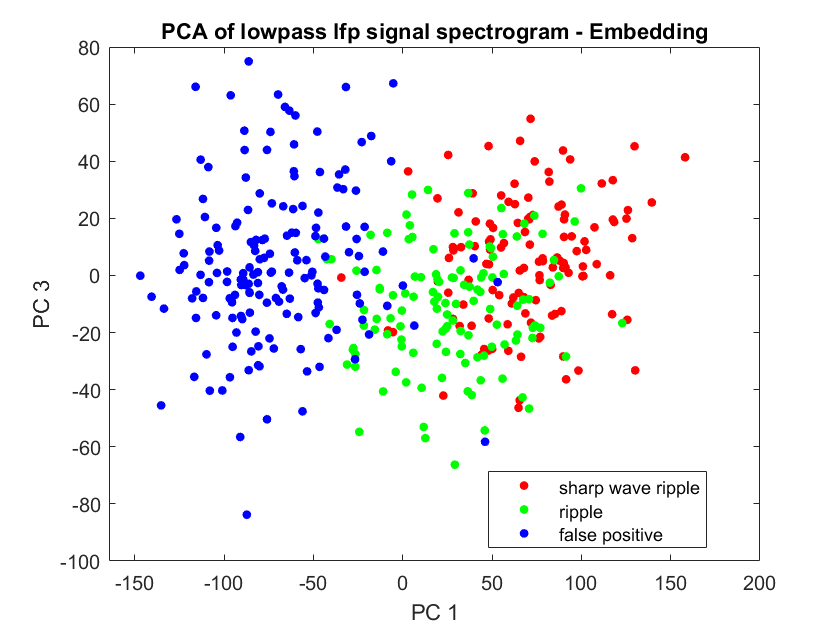

figure()
gscatter(score(:,1),score(:,3), ripples.eventID)
title("PCA of lowpass lfp signal spectrogram - Embedding")
xlabel('PC 1')
ylabel('PC 3')
legend('sharp wave ripple','ripple','false positive')

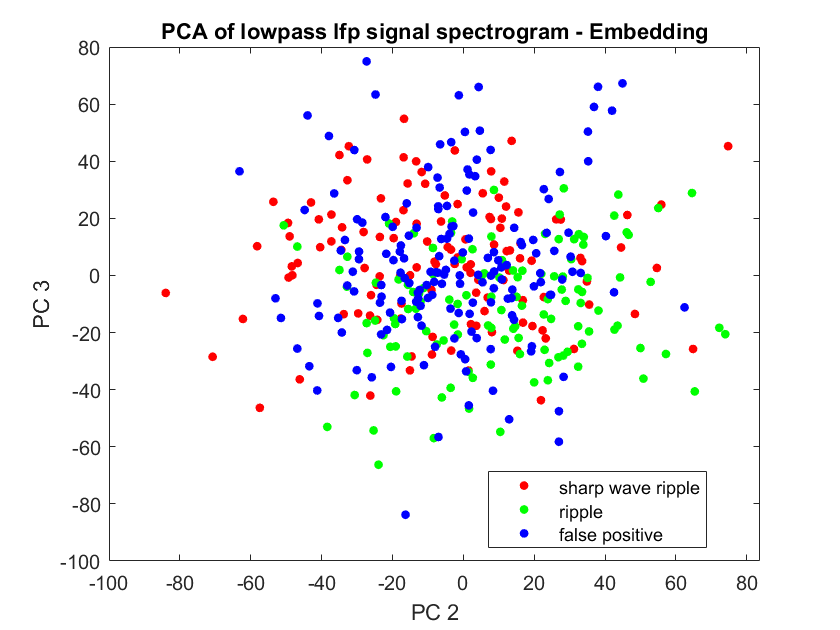

figure()
gscatter(score(:,2),score(:,3), ripples.eventID)
title("PCA of lowpass lfp signal spectrogram - Embedding")
xlabel('PC 2')
ylabel('PC 3')
legend('sharp wave ripple','ripple','false positive')

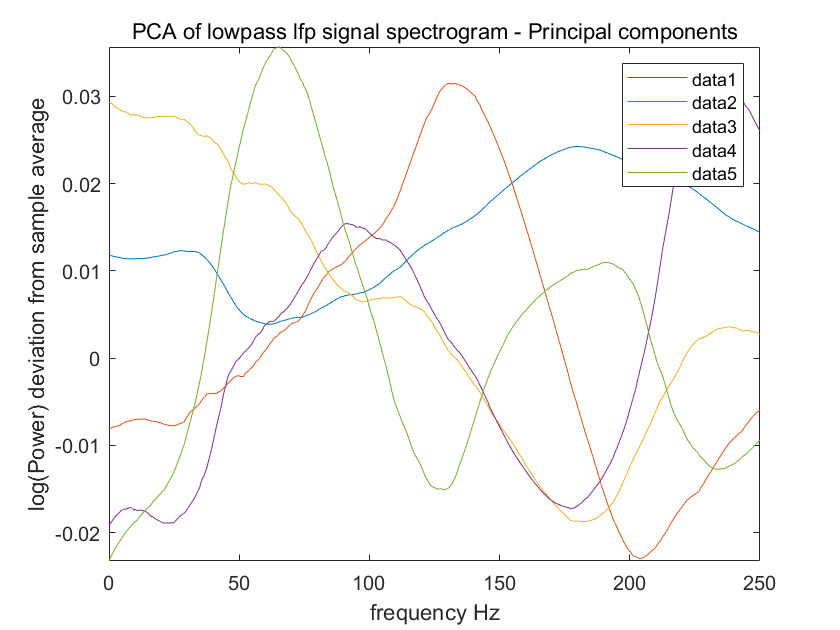


% Visualize principal components of ripple envelope
figure()
plot(rippleEpisodes.spectrogram_frequencies, coeff(:,1:5))
subtitle("PCA of lowpass lfp signal spectrogram - Principal components");
axis tight
xlabel('frequency Hz')                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        
ylabel('log(Power) deviation from sample average')
legend()

The signal power (absolute value of the hilbert transform) is also the envelope of the bandpass filtered lfp signal.

Next, we try to identify variations in the envolope of the bandpass signal to learn about temporal signatures of the ripple events.

Again we average over all instances of a class and all channels. Dashed lines indicate the class wise standard deviation.

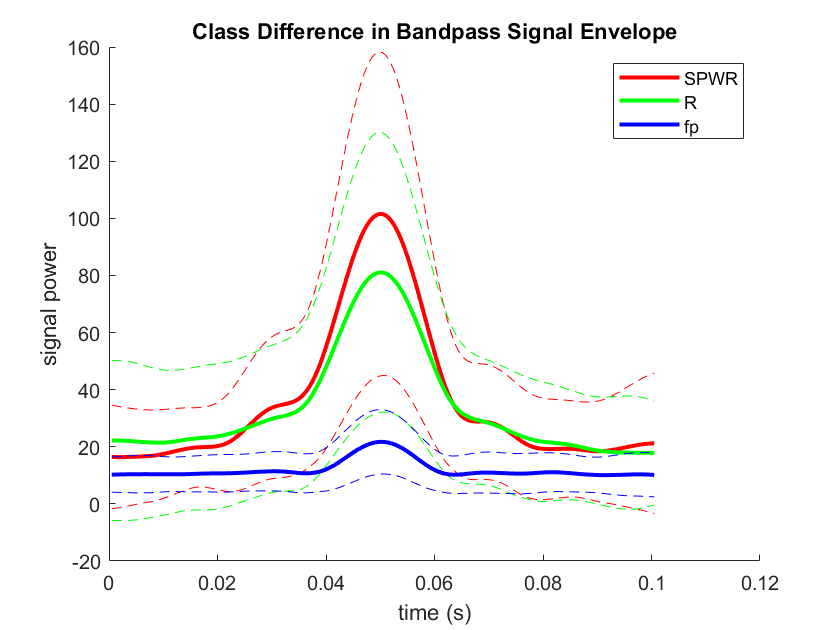

%% Display group differences in the envelope of the bandpass signal
figure()
hold on;
group_color = ['r','g','b'];
for group = 0:2
    group_mean = mean(rippleEpisodes.bandpass_power(ripples.eventID==group,:,:),[1 3]);
    group_std = std(rippleEpisodes.bandpass_power(ripples.eventID==group,:,:),[],[1 3]);
    plot((1:eventWindowFrames)/lfp.samplerate,group_mean-group_std,'--','Color',group_color(group+1))
    plot((1:eventWindowFrames)/lfp.samplerate,group_mean,'Color',group_color(group+1),'LineWidth',2)
    plot((1:eventWindowFrames)/lfp.samplerate,group_mean+group_std,"--",'Color',group_color(group+1))
end
hold off;
title('Class Difference in Bandpass Signal Envelope')
legend("","SPWR","","","R","","","fp","")
xlabel('time (s)')
ylabel("signal power")

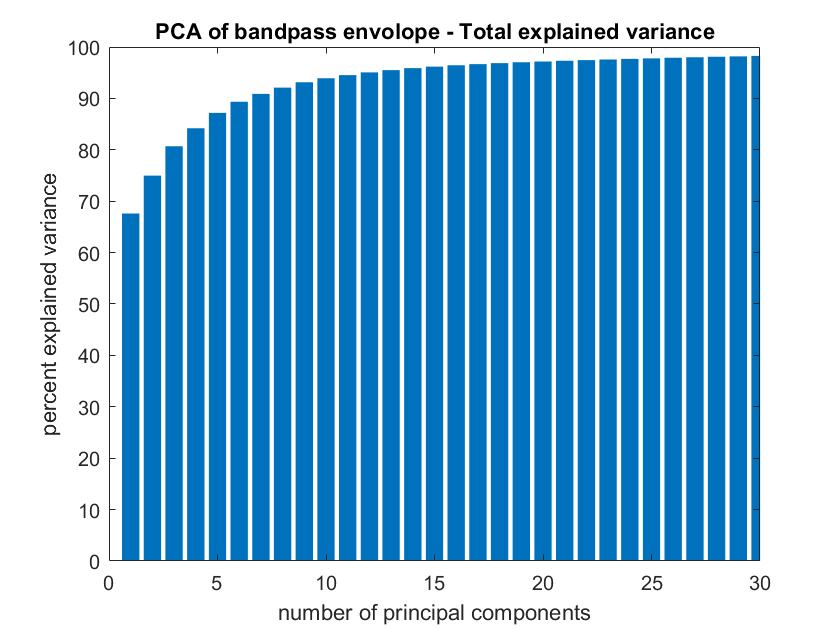

%% Perform PCA on analytic envelope of bandpass signal
% the analytic envelope of a signal is given by the absolute value of its
% hilbert transform as allready calculated for lfp.bandpass_power
% the envelope of each episode is equivalent to the
% rippleEpisode.banpdass_power field
[coeff,score, ~, ~, explained, ~ ] = pca(reshape(rippleEpisodes.bandpass_power,ripples.n,[]));
rippleEpisodes.bandpass_power_features = score(:,1:5);

%% Visualize success of PCA on analytic envelope of bandpass signal
% visualize explained variance by first n components
figure()
bar(cumsum(explained))
title('PCA of bandpass envolope - Total explained variance')
xlabel('number of principal components')
ylabel('percent explained variance')
xlim([0 30])

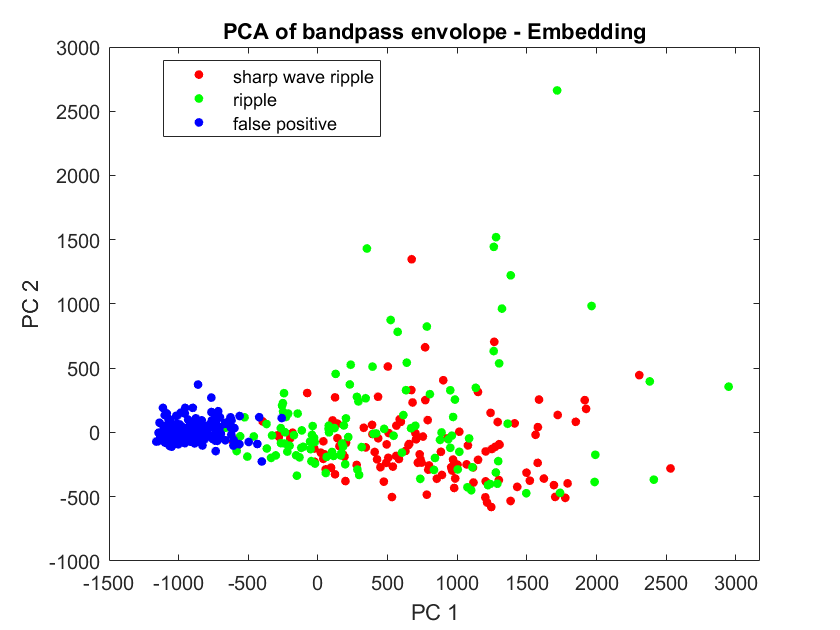


% Visualize PCA projection of ripples
figure()
gscatter(score(:,1),score(:,2), ripples.eventID)
title("PCA of bandpass envolope - Embedding")
xlabel('PC 1')
ylabel('PC 2')
legend('sharp wave ripple','ripple','false positive');

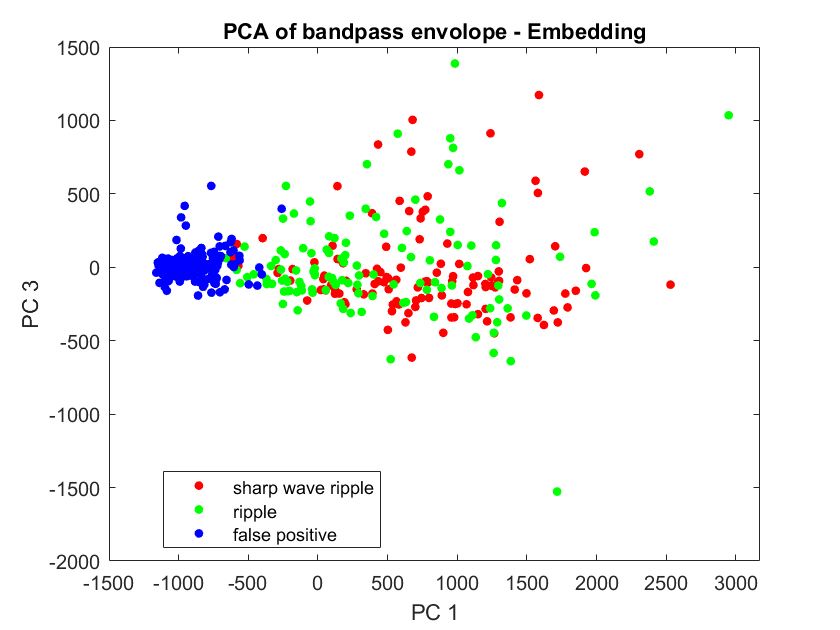

% Visualize PCA projection of ripples
figure()
gscatter(score(:,1),score(:,3), ripples.eventID)
title("PCA of bandpass envolope - Embedding")
xlabel('PC 1')
ylabel('PC 3')
legend('sharp wave ripple','ripple','false positive');

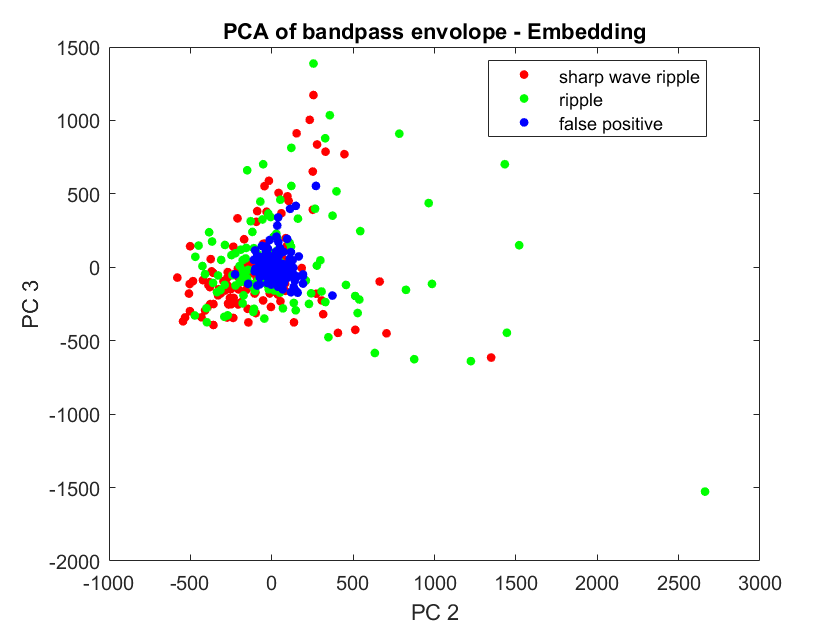

% Visualize PCA projection of ripples
figure()
gscatter(score(:,2),score(:,3), ripples.eventID)
title("PCA of bandpass envolope - Embedding")
xlabel('PC 2')
ylabel('PC 3')
legend('sharp wave ripple','ripple','false positive');

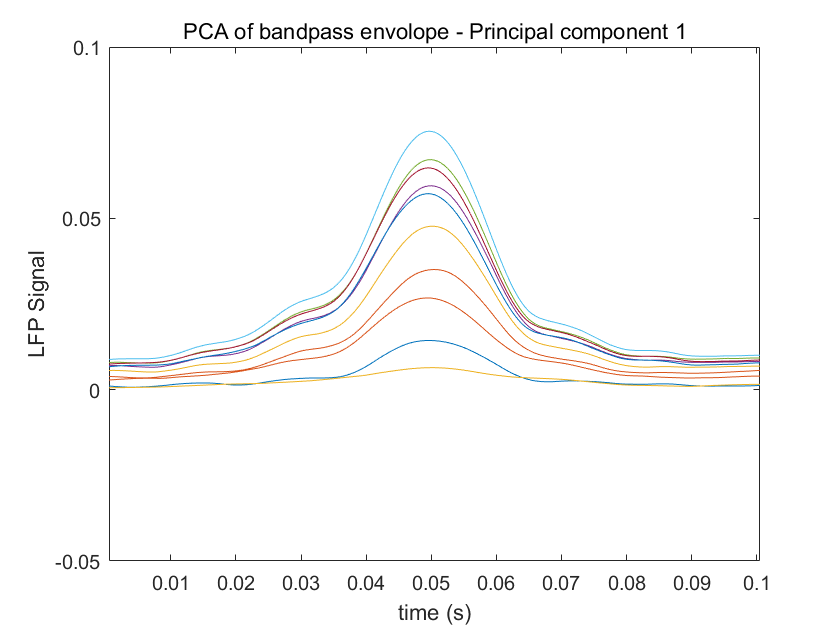

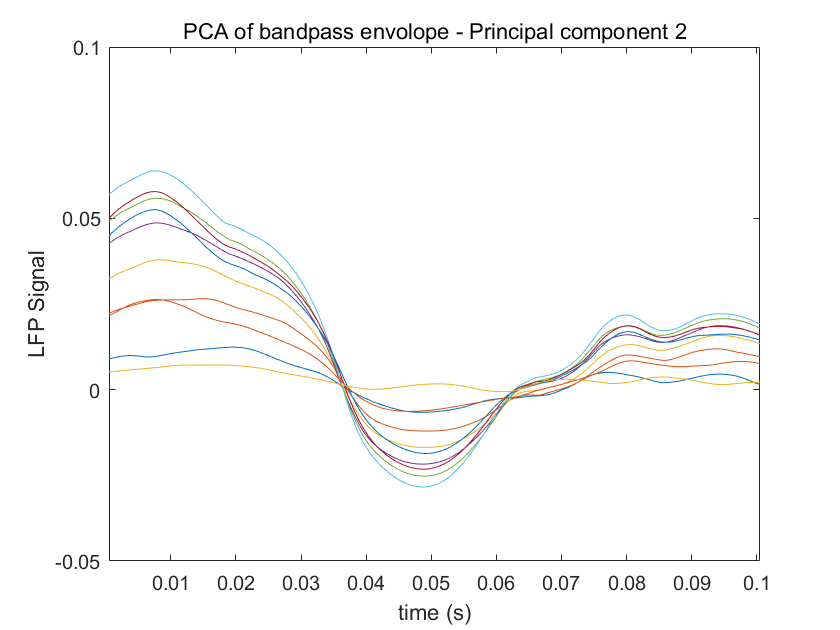

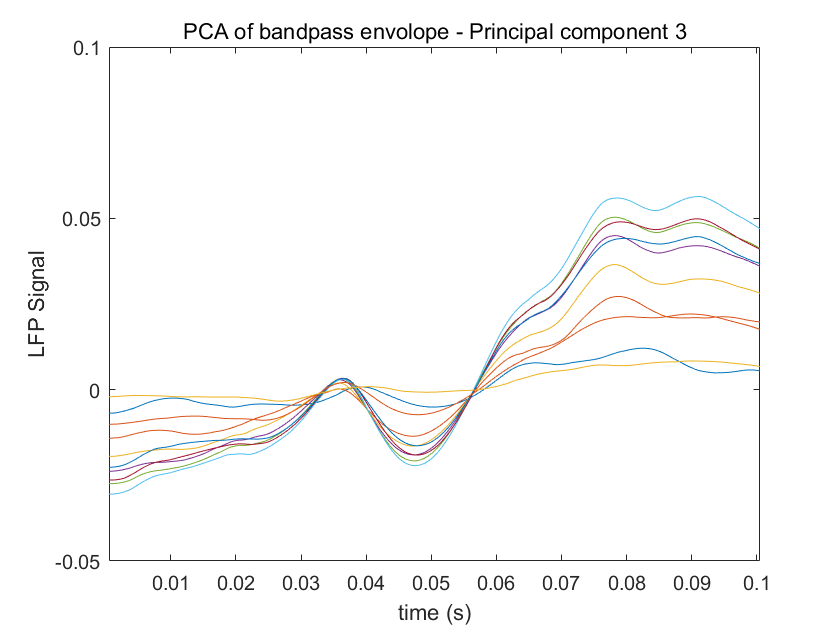

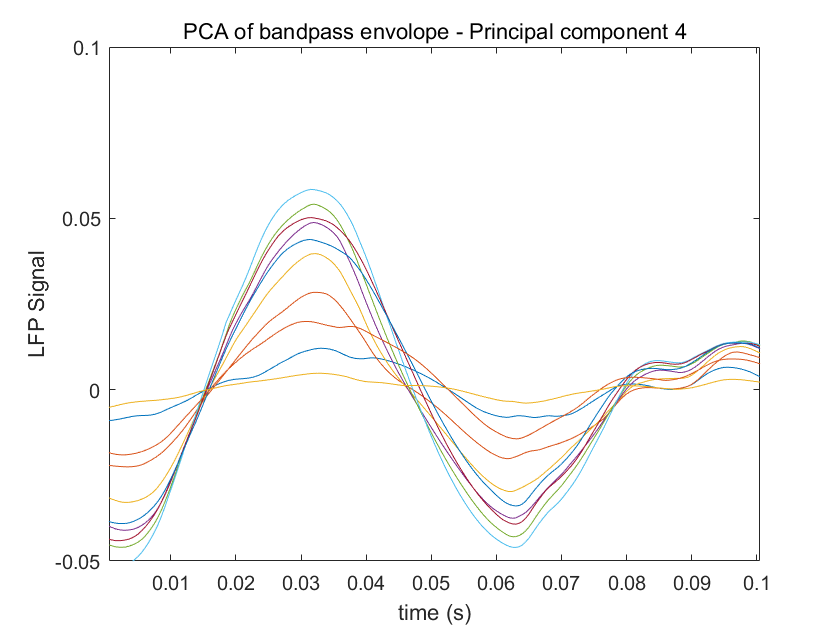

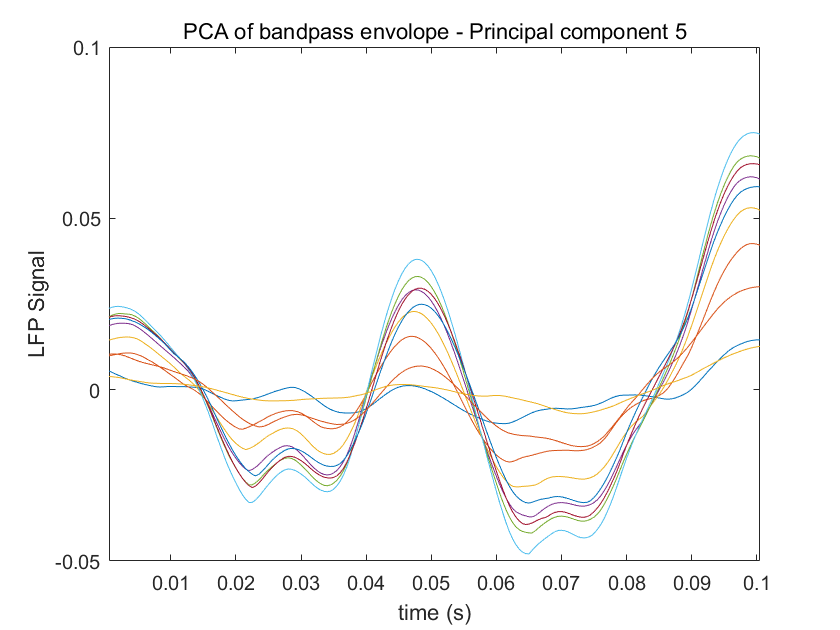



% Visualize principal components of ripple envelope
for i = 1:5
    pc = reshape(coeff(:,i),eventWindowFrames,numel(lfp.ripple_channels));
    figure()
    plot((1:eventWindowFrames)/lfp.samplerate, pc)
    subtitle("PCA of bandpass envolope - Principal component " + i);
    axis tight
    ylim([-0.05 0.1]);
    xlabel('time (s)')                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        
    ylabel('LFP Signal')
    %legend(split(num2str(lfp.ripple_channels)))
end

Lastly, use PCA to directly identify components of variation in the raw bandpass signal

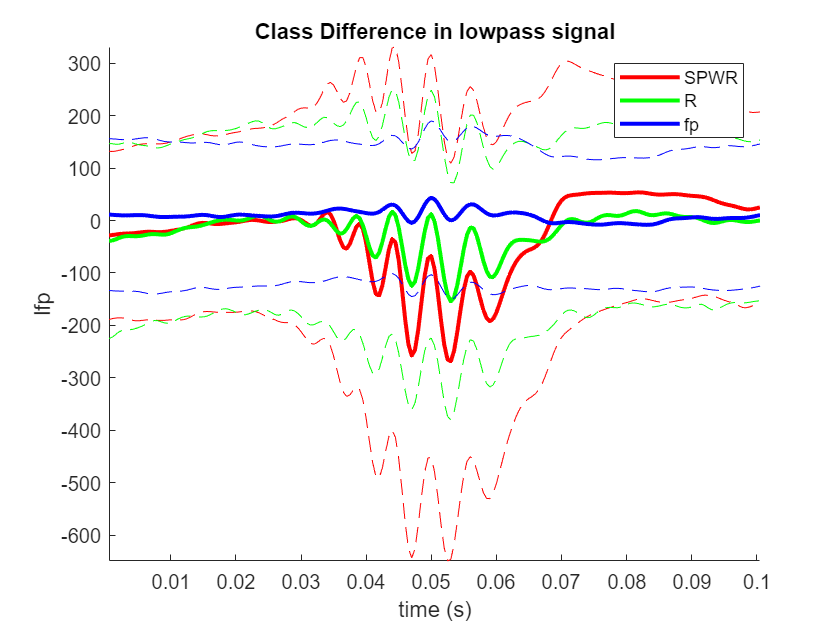

%% Display group differences in the lowpass signal
figure()
hold on;
group_color = ['r','g','b'];
for group = 0:2
    group_mean = mean(rippleEpisodes.lowpass(ripples.eventID==group,:,:),[1 3]);
    group_std = std(rippleEpisodes.lowpass(ripples.eventID==group,:,:),[],[1 3]);
    plot((1:eventWindowFrames)/lfp.samplerate,group_mean-group_std,'--','Color',group_color(group+1))
    plot((1:eventWindowFrames)/lfp.samplerate,group_mean,'Color',group_color(group+1),'LineWidth',2)
    plot((1:eventWindowFrames)/lfp.samplerate,group_mean+group_std,"--",'Color',group_color(group+1))
end
hold off;
axis tight
title('Class Difference in lowpass signal')
legend("","SPWR","","","R","","","fp","")
xlabel('time (s)')
ylabel("lfp")

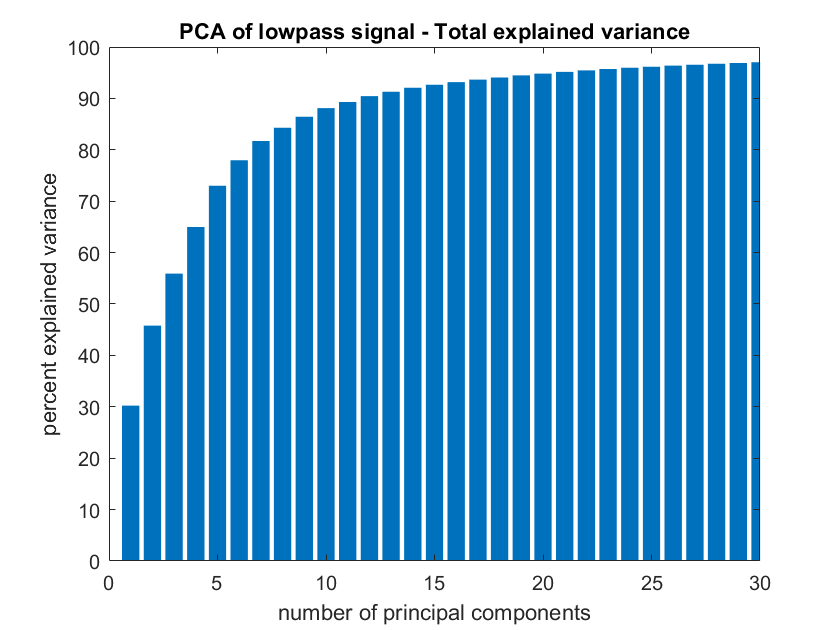


%% Perform PCA on lowpass filtered lfp signal
[coeff,score, ~, ~, explained, ~ ] = pca(reshape(rippleEpisodes.lowpass,ripples.n,[]));
rippleEpisodes.lowpass_features = score(:,1:10);

%% Visualize success of PCA on lowpass signal
% visualize explained variance by first n components
figure()
bar(cumsum(explained))
title('PCA of lowpass signal - Total explained variance')
xlabel('number of principal components')
ylabel('percent explained variance')
xlim([0 30])

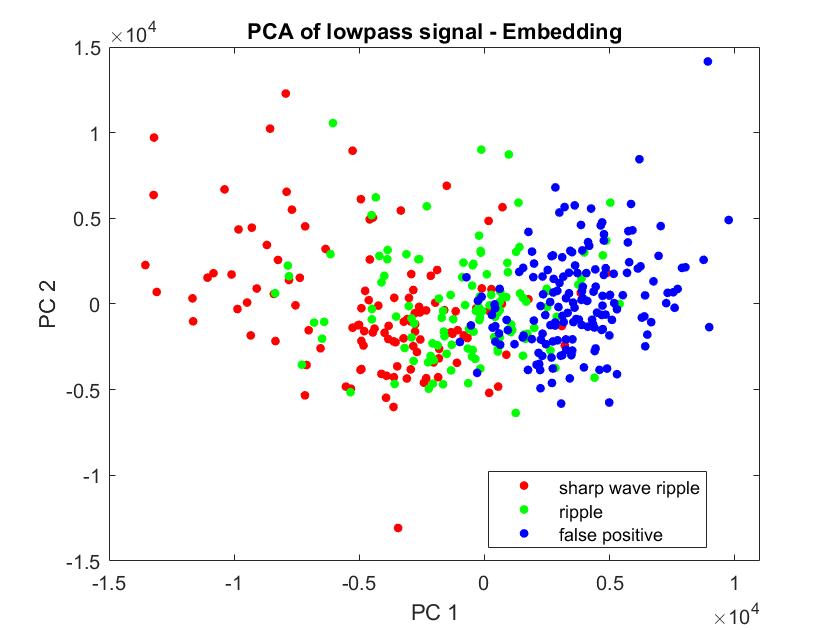


% Visualize PCA projection of ripples
figure()
gscatter(score(:,1),score(:,2), ripples.eventID)
title("PCA of lowpass signal - Embedding")
xlabel('PC 1')
ylabel('PC 2')
legend('sharp wave ripple','ripple','false positive');

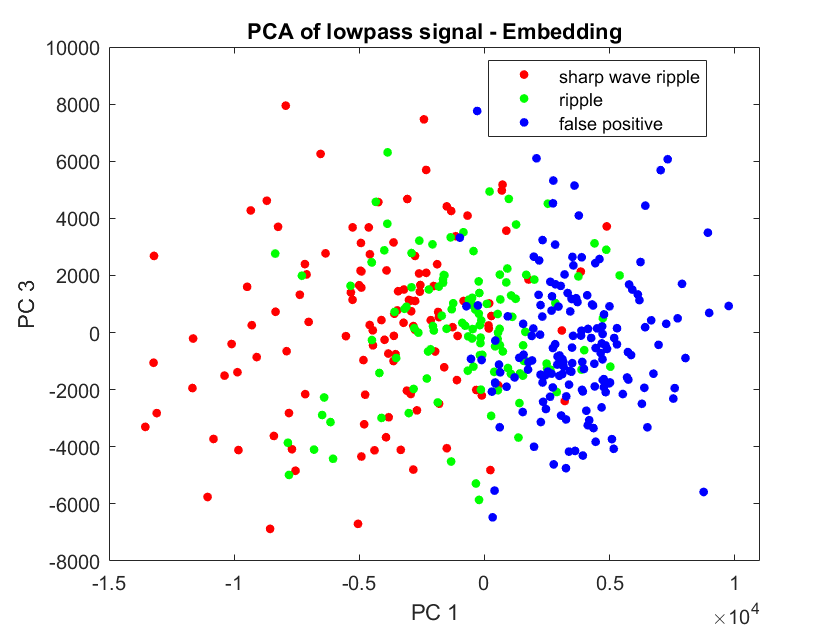

% Visualize PCA projection of ripples
figure()
gscatter(score(:,1),score(:,3), ripples.eventID)
title("PCA of lowpass signal - Embedding")
xlabel('PC 1')
ylabel('PC 3')
legend('sharp wave ripple','ripple','false positive');

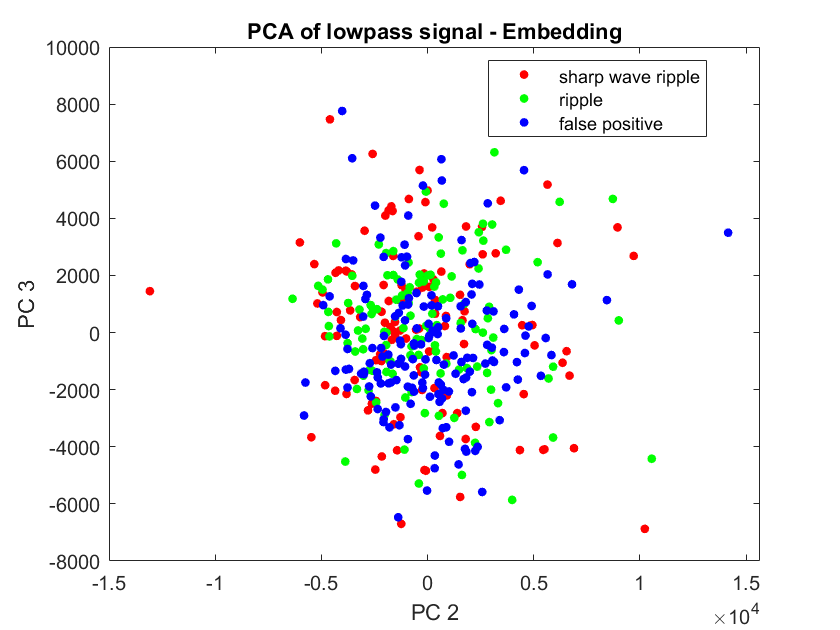

% Visualize PCA projection of ripples
figure()
gscatter(score(:,2),score(:,3), ripples.eventID)
title("PCA of lowpass signal - Embedding")
xlabel('PC 2')
ylabel('PC 3')
legend('sharp wave ripple','ripple','false positive');

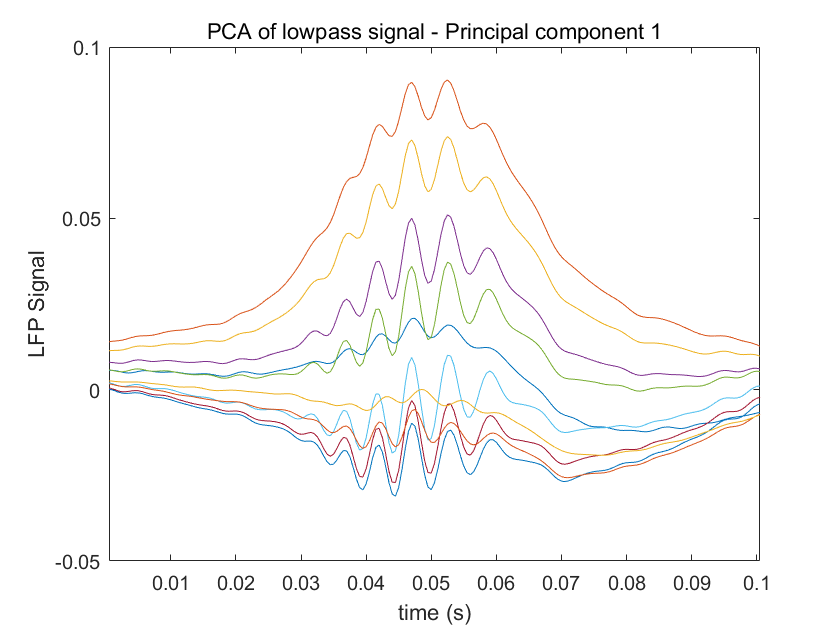

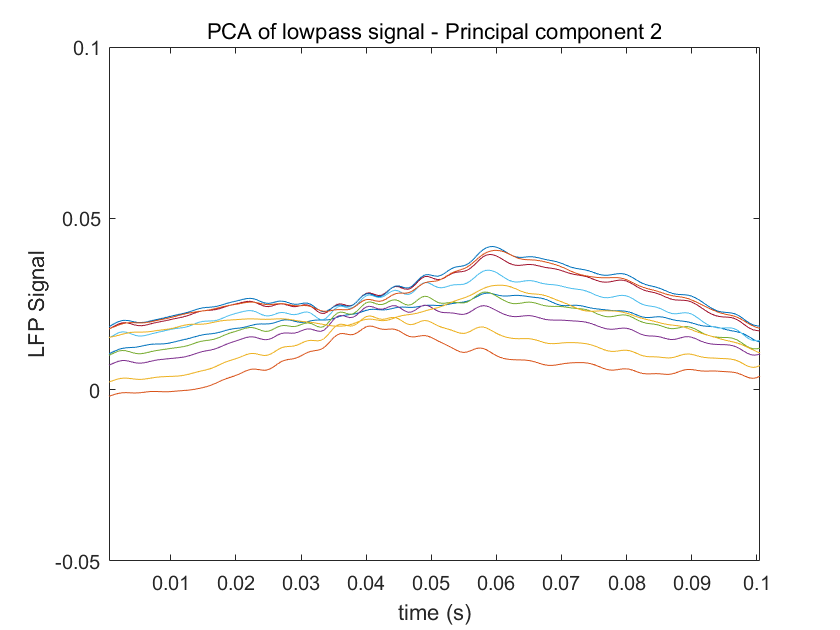

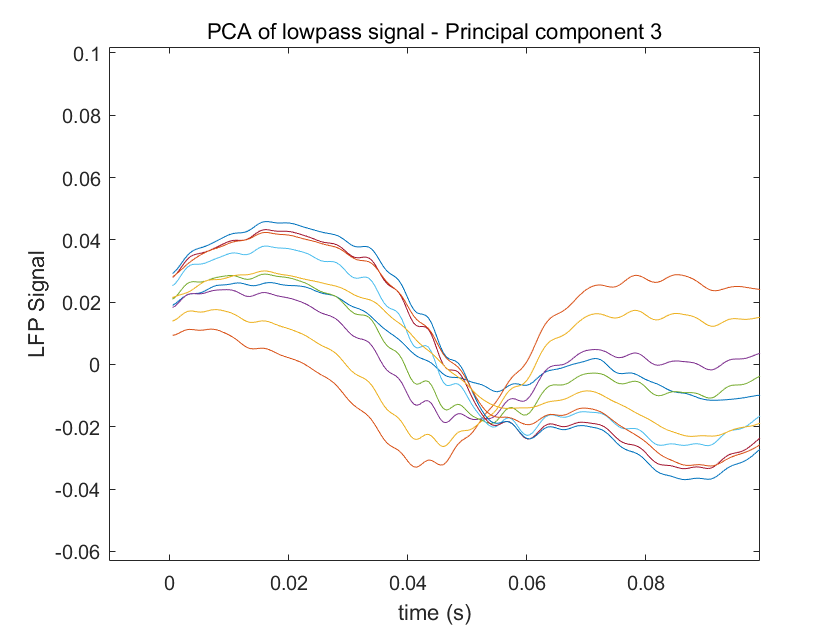

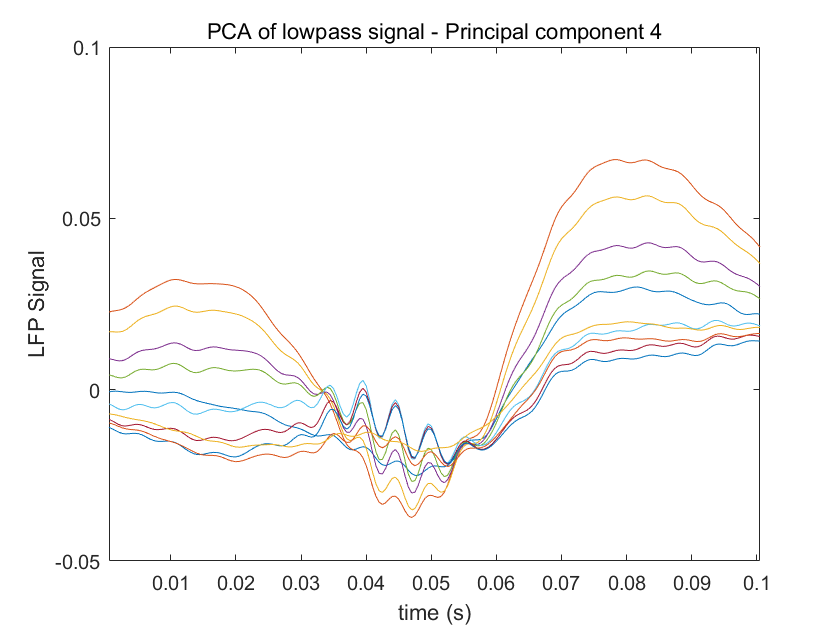

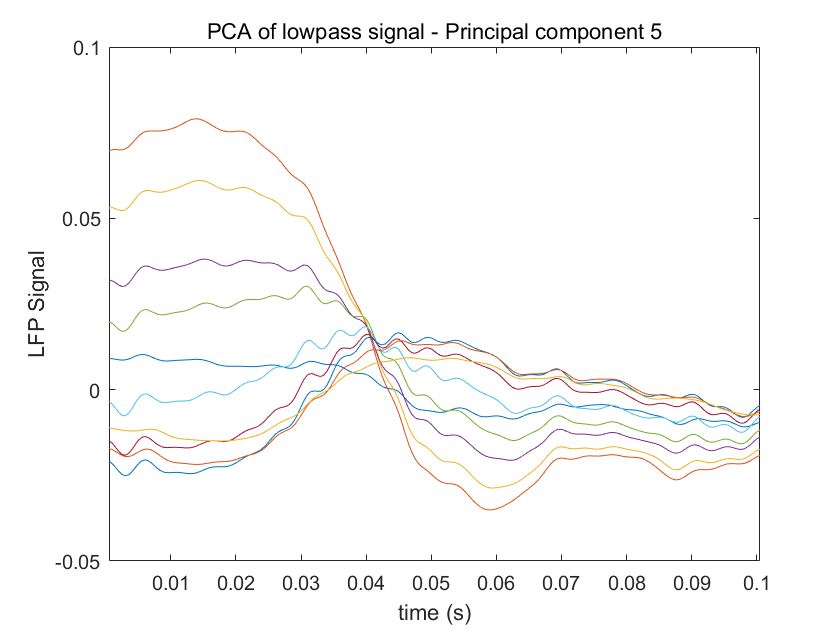


% Visualize principal components of ripple envelope
for i = 1:5
    pc = reshape(coeff(:,i),eventWindowFrames,numel(lfp.ripple_channels));
    figure()
    plot((1:eventWindowFrames)/lfp.samplerate, pc)
    subtitle("PCA of lowpass signal - Principal component " + i);
    axis tight
    ylim([-0.05 0.1]);
    xlabel('time (s)')                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        
    ylabel('LFP Signal')
end

%% Save features to table
featureTable = table(ripples.lowpass_min, ripples.lowpass_max, ripples.lowpass_mean, ripples.lowpass_std, ...
    ripples.lowpass_meanChannelSpread, ripples.bandpass_mean, ripples.bandpass_std, ...
    ripples.bandpass_maxSlope, ripples.bandpass_meanAbsSlope, ripples.bandpass_meanFreq,...
    ripples.bandpass_peak2peak, rippleEpisodes.bandpass_power_features,...
    rippleEpisodes.lowpass_features, rippleEpisodes.spectrogram_features, 'VariableNames',{'lowpass min','lowpass max','lowpass mean','lowpass std','lowpass mean Channel spread','bandpass mean','bandpass std','bandpass maxSlope',...
    'bandpass meanAbsSlope','bandpass meanFreq','bandpass p2p','envelope PCA','lowpass PCA','Spectrogram PCA'});
featureTable = splitvars(featureTable);
%featureTable(:,'center Timepoint') = table(rippleEpisodes.centralFrames/lfp.samplerate);

What subset of features taken together is informative to discriminate the different classes ?

We can train a linear classifier with L1 regularization to find solutions that use only a minimal number of feature dimension to construct the separating hyperplane

First, try to identify a feature set that is informative for false positive vs. {SPWR, Ripple} classification

We can achieve a cross validated classification accuracy of ~80-90% using only ~10-20% of the features. 

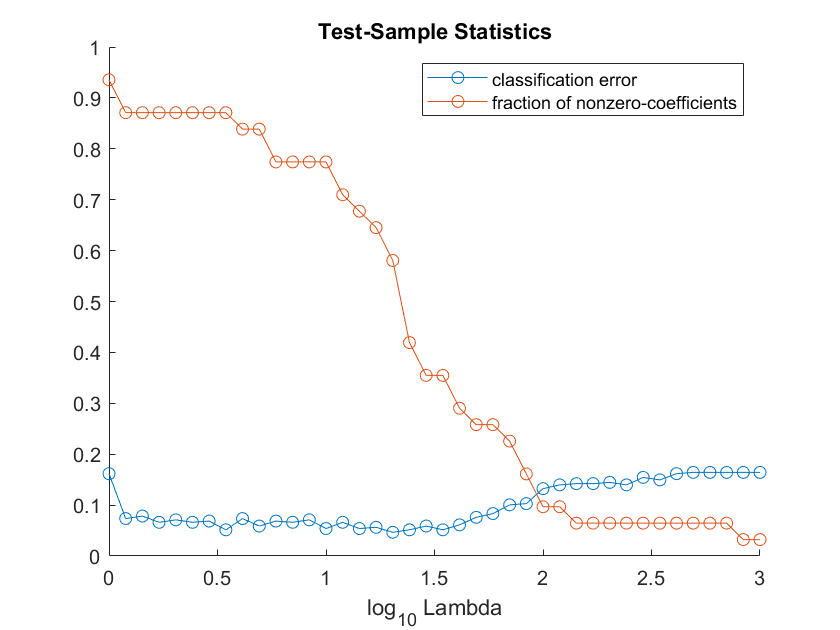

%% Train a linear model for detection of ripples with L1 Regularization
isRipple = ripples.eventID ~= 2;

lambda = logspace(0,3,40);
CVmodel = fitclinear(featureTable,isRipple,'KFold',5,'Regularization','lasso','Lambda',lambda);
classificationError = kfoldLoss(CVmodel); % calculate classification loss for each regularization level
model = fitclinear(featureTable,isRipple,'Regularization','lasso','Lambda',lambda);
numberNonzeroCoefficients = sum(model.Beta~=0);
% Find best regularization strength
figure;
hold on;
plot(log10(lambda),classificationError,'-o')
plot(log10(lambda),numberNonzeroCoefficients/numel(model.PredictorNames),'-o'); 
hold off;
legend('classification error','fraction of nonzero-coefficients');
xlabel('log_{10} Lambda')
title('Test-Sample Statistics')
hold off

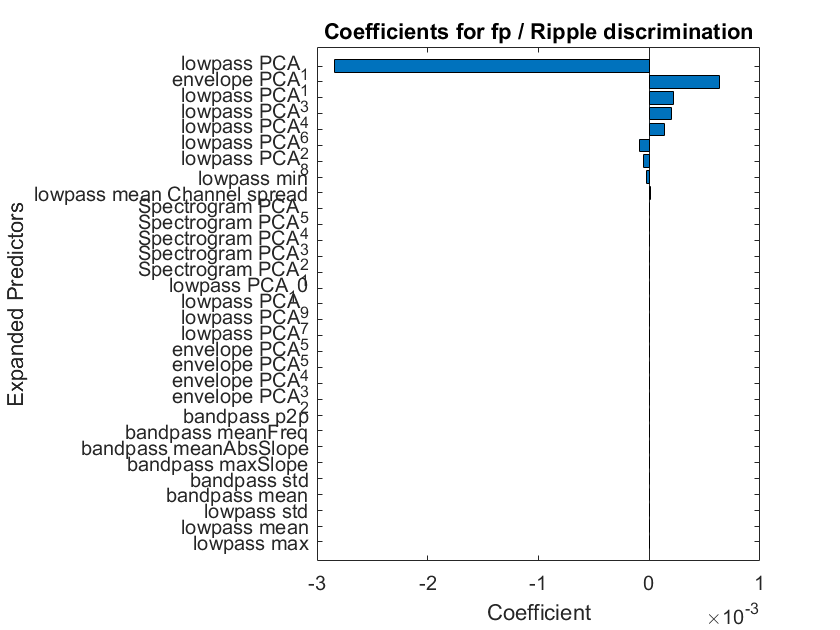

%% fit a model with a reasonable regularization strength and visualize feature importance
lambda = 10^1.8;
model = fitclinear(featureTable,isRipple,'Regularization','lasso','Lambda',lambda);
p = length(model.Beta);
[sortedCoefs,expandedIndex] = sort(model.Beta,ComparisonMethod="abs");
sortedExpandedPreds = model.ExpandedPredictorNames(expandedIndex);
figure()
bar(sortedCoefs,Horizontal="on")
yticks(1:p)
yticklabels(sortedExpandedPreds(1:end))
xlabel("Coefficient")
ylabel("Expanded Predictors")
title("Coefficients for fp / Ripple discrimination")

We can repeat the exaxt same analysis for discrimatiing between putative SPWR / Ripple Events.

These categories are not as readily resolved using any of the provided features which is reflected in the mediocre classification accuracy of ~70-60%

We need to retain about 30-10% of the features.

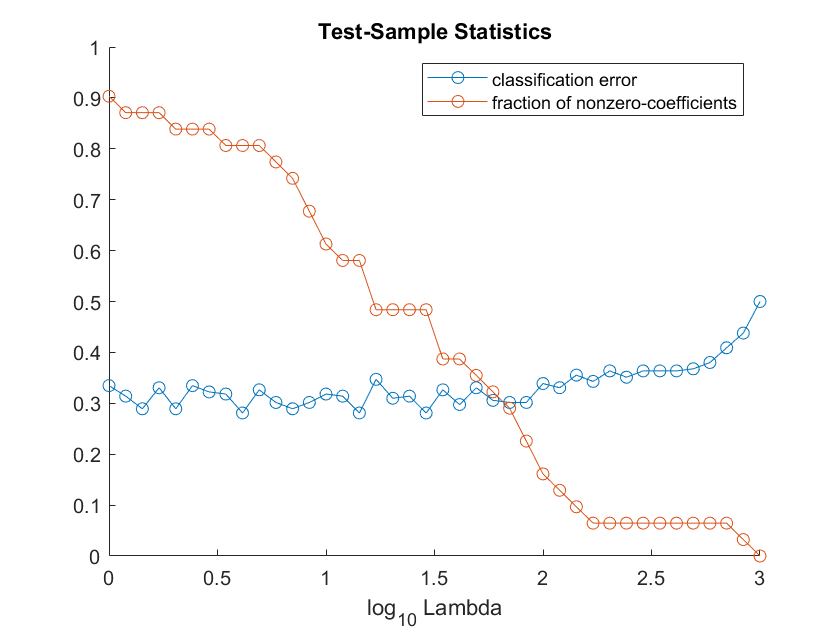

%% Train a linear model for discrimination of ripples from SPW-R with L1 Regularization
featureTableRipplesOnly = featureTable(isRipple,:);
isSPWR = ripples.eventID(isRipple);

lambda = logspace(0,3,40);
CVmodel = fitclinear(featureTableRipplesOnly,isSPWR,'KFold',5,'Regularization','lasso','Lambda',lambda);
classificationError = kfoldLoss(CVmodel); % calculate classification loss for each regularization level
model = fitclinear(featureTableRipplesOnly,isSPWR,'Regularization','lasso','Lambda',lambda);
numberNonzeroCoefficients = sum(model.Beta~=0);
% Find best regularization strength
figure;
hold on;
plot(log10(lambda),classificationError,'-o')
plot(log10(lambda),numberNonzeroCoefficients/numel(model.PredictorNames),'-o'); 
hold off;
legend('classification error','fraction of nonzero-coefficients');
xlabel('log_{10} Lambda')
title('Test-Sample Statistics')
hold off

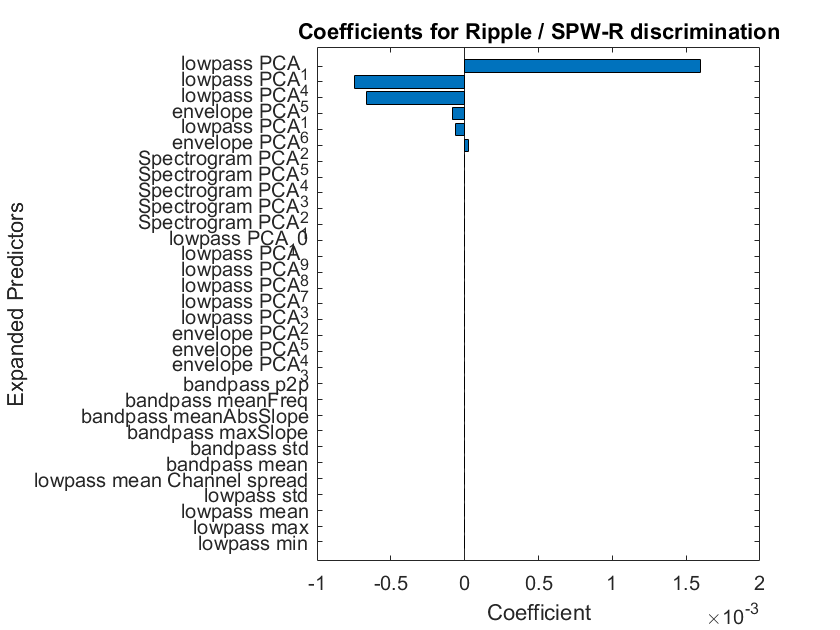

%% fit a model with a reasonable regularization strength and visualize feature importance
lambda = 10^1.8;
model = fitclinear(featureTableRipplesOnly,isSPWR,'Regularization','lasso','Lambda',lambda);
p = length(model.Beta);
[sortedCoefs,expandedIndex] = sort(model.Beta,ComparisonMethod="abs");
sortedExpandedPreds = model.ExpandedPredictorNames(expandedIndex);
figure()
bar(sortedCoefs,Horizontal="on")
yticks(1:p)
yticklabels(sortedExpandedPreds(1:end))
xlabel("Coefficient")
ylabel("Expanded Predictors")
title("Coefficients for Ripple / SPW-R discrimination")